% Test script for detecting squares, circles, and crosses on a Tic Tac Toe board

% Specify the path to your image file
image_path = ['testing1.png'];



% --- Detect Circles and Crosses ---
% Load the image for circle and cross detection
image = imread(image_path);

% --- Detect Square Centers ---
% Call the function to detect square centers
square_centers = detectSquareCenters(image);

% Detect circles
circle_centers = find_circles(image);

% Detect crosses
cross_centers = find_crosses(image);

boardMatrixFill(square_centers, cross_centers, circle_centers);


Current Board:
 . | . | O
---+---+---
 O | X | .
---+---+---
 . | . | X




% --- Display the results ---
figure;
imshow(image);
hold on;
title('Detected Square Centers, Circles, and Crosses');

% Plot the detected square centers (green circles)
if ~isempty(square_centers)
    plot(square_centers(:, 1), square_centers(:, 2), 'go', 'MarkerSize', 10, 'LineWidth', 2);
    disp('Detected Square Centers:');
    disp(array2table(square_centers, 'VariableNames', {'X_Coordinate', 'Y_Coordinate'}));
else
    disp('No Square Centers Detected');
end

Detected Square Centers:


    X_Coordinate    Y_Coordinate
    ____________    ____________

         47             57.5    
        147             57.5    
        247             57.5    
         47            150.5    
        147            150.5    
        247            150.5    
         47            243.5    
        147            243.5    
        247            243.5    




% Plot the detected circles (red circles)
if ~isempty(circle_centers)
    plot(circle_centers(:, 1), circle_centers(:, 2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
    disp('Detected Circle Centers:');
    disp(array2table(circle_centers, 'VariableNames', {'X_Coordinate', 'Y_Coordinate'}));
end

Detected Circle Centers:


    X_Coordinate    Y_Coordinate
    ____________    ____________

       251.28          49.023   
       46.597          150.22   




% Plot the detected crosses (blue X's)
if ~isempty(cross_centers)
    plot(cross_centers(:, 1), cross_centers(:, 2), 'bx', 'MarkerSize', 10, 'LineWidth', 2);
    disp('Detected Cross Centers (X):');
    disp(array2table(cross_centers, 'VariableNames', {'X_Coordinate', 'Y_Coordinate'}));
else
    disp('No Cross Centers Detected');
end

Detected Cross Centers (X):


    X_Coordinate    Y_Coordinate
    ____________    ____________

        151             146     
        251             246     



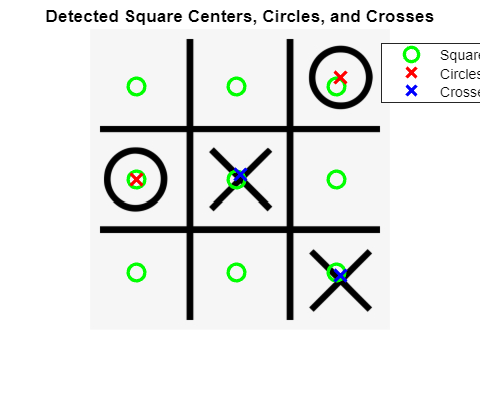


legend('Square Centers', 'Circles', 'Crosses');
hold off;